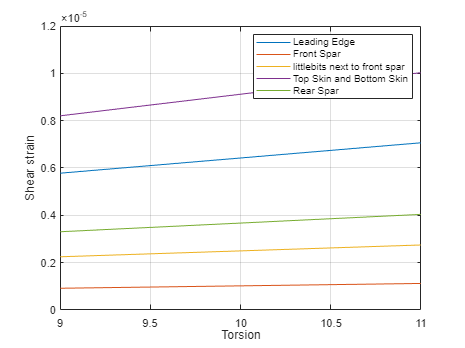

clc
clear

%% theory for shear flow in tension

Force = 222.411084;
distspar = 0.3354;

couple = Force * distspar;
T = 0:0.1:couple;

G = 28e9;

t = [0.64 1.7 2.34 0.64 2.23 1.59] .* 1e-3;


q1 = 11.50904165 * T;
q2 = 16.34019591 * T;


strain1_8e = q1 / (G * t(1)); 
strain1_8i = (q2-q1) / (G * t(2)); %front 
strain1_2 = q2 / (G * t(3)); %and 7-8
strain2_3 = q2 / (G * t(4)); %and 6-7
strain3_6 = q2 / (G * t(6));

figure
plot(T,strain1_8e,"DisplayName","Leading Edge")
hold on
plot(T,strain1_8i,"DisplayName","Front Spar")
plot(T,strain1_2,"DisplayName","littlebits next to front spar")
plot(T,strain2_3,"DisplayName","Top Skin and Bottom Skin")

plot(T,strain3_6,"DisplayName", "Rear Spar")

xlabel("Torsion")
ylabel("Shear strain")
grid on
xlim([9 11])
legend 

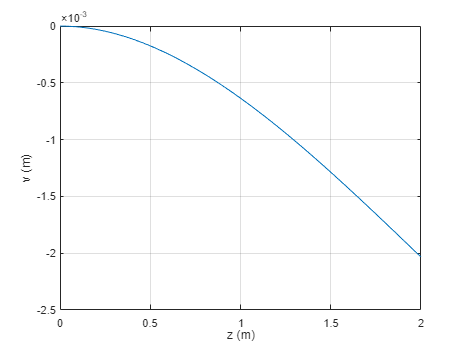

%% theory for buckling 

E = 73.1e9;

L=4; %in m
I11mm = 897142.8; % in mm4 
I22mm = 7601609; %in mm4
I11 = I11mm*1e-12;
I22 = I22mm*1e-12;

yieldstress =  280e6;
Rtrans = pi * sqrt( 2*E /yieldstress);

Leff = 2*L;

Pcrit = pi^2 * E * I11/ (Leff)^2;




%% theory for deflection

z = 0:0.01:2;
Lbending =2;
P = 50;

v= (-P/(E * I11)) * (Lbending * z .^2 ./ 2 - z .^3 ./ 6);

figure

plot(z,v)

grid on
xlabel("z (m)")
ylabel("v (m)")